## Chapter 2: PID controller

### 2.1 Traditional PID controller

clear all;
close all;
ts = 0.001; % sampling time

% Plant to control Gp(s) = 523500/(s^3 + 87.35s^2 + 10470s)
sys = tf(523500, [1 87.35 10470 0]);

dsys = c2d(sys,ts,'z') % Discrete the plant

dsys =
 
  8.533e-05 z^2 + 0.0003338 z + 8.169e-05
  ---------------------------------------
    z^3 - 2.906 z^2 + 2.823 z - 0.9164
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


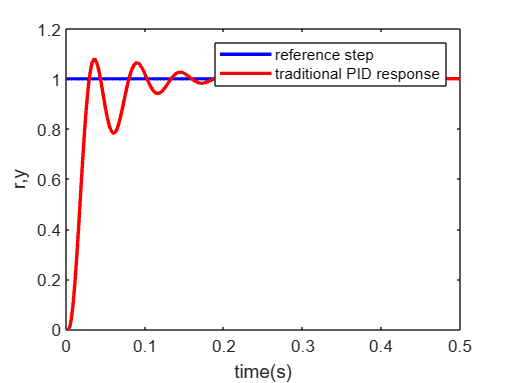

[num,den] = tfdata(dsys,'v');

% initial conditions
u_1 = 0;u_2 = 0;u_3 = 0;u_4 = 0;
y_1 = 0;y_2 = 0; y_3 = 0;
ei = 0;

% Parameters of PID controller

kp = 0.96;ki = 0.03;kd = 0.01;

error_1 = 0;

for k = 1:500

    time(k) = k*ts; % time of computation of response

    % Discrete response is equal to
    yd(k) = 1.0;
    y(k) = -den(2)*y_1 - den(3)* y_2 - den(4)*y_3 + num(1)*u_1 + num(2)*u_2 + num(3)*u_3 + num(4)*u_4;

    % Calculation of P
    error(k) = yd(k) - y(k);
    
    % Calculation of D
    derror(k) = error(k) - error_1;
    
    % Calculation of I
    ei = ei + error(k)*ts;

   % PID Controller
    u(k) = kp*error(k) +kd*derror(k)/ts+ki*ei;
    
    % Actualize the inputs and outputs
    u_4=u_3;u_3=u_2;u_2=u_1;u_1=u(k);
    y_3=y_2;y_2=y_1;y_1=y(k);
    error_1 = error(k);
end

% Plot step response
figure(1);
plot(time,yd,'b',time,y,'r','linewidth',2);
xlabel('time(s)');ylabel('r,y');
legend('reference step','traditional PID response')

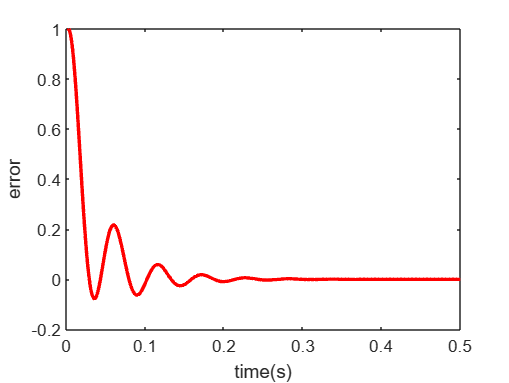

figure(2);
plot(time,yd-y,'r','linewidth',2);
xlabel('time(s)');ylabel('error');

### 2.2 Expert PID control

clear all;
close all;
ts = 0.001; % sampling time

% Plant to control Gp(s) = 523500/(s^3 + 87.35s^2 + 10470s)
sys = tf(523500, [1 87.35 10470 0]);

dsys = c2d(sys,ts,'z') % Discrete the plant

dsys =
 
  8.533e-05 z^2 + 0.0003338 z + 8.169e-05
  ---------------------------------------
    z^3 - 2.906 z^2 + 2.823 z - 0.9164
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


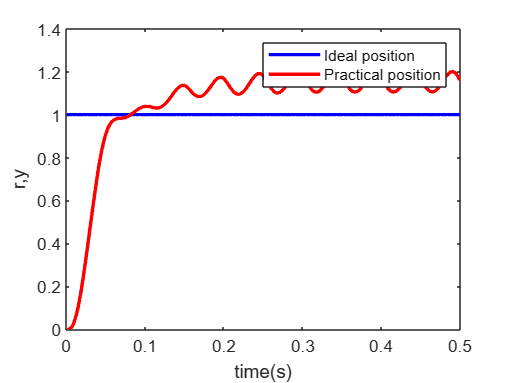

[num,den] = tfdata(dsys,'v');

% initial conditions
u_1 = 0;u_2 = 0;u_3 = 0;u_4 = 0;
y_1 = 0;y_2 = 0; y_3 = 0;
ei = 0;

% Parameters of PID controller

kp = 0.6;ki = 0.03;kd = 0.01;

error_1 = 0; derror_1 = 0;

for k = 1:500

    time(k) = k*ts; % time of computation of response

    % Discrete response is equal to
    yd(k) = 1.0;
    y(k) = -den(2)*y_1 - den(3)* y_2 - den(4)*y_3 + num(1)*u_1 + num(2)*u_2 + num(3)*u_3 + num(4)*u_4;

    % Calculation of P
    error(k) = yd(k) - y(k);
    
    % Calculation of D
    derror(k) = error(k) - error_1;
    
    % Calculation of I
    ei = ei + error(k)*ts;

   % PID Controller
    u(k) = kp*error(k) +kd*derror(k)/ts+ki*ei;
    
    % Expert control rules

    % Rule 1: use unloop controller to minimize quickly the error
    if abs(error(k)) > 0.8
        u(k) = 0.45;
    elseif abs(error(k)) > 0.4
        u(k) = 0.4;
    elseif abs(error(k)) > 0.2
        u(k) = 0.12;
    elseif abs(error(k)) > 0.01
        u(k) = 0.1;
    end

    % Rule 2: Condition on error
    if error(k)*derror(k) > 0 | (derror(k) == 0)
        M2 = 0.05;
        if abs(error(k)) >= M2
            % use strong P controller (k1 > 1)
            u(k) = u_1 + 2*(kp*(derror(k)) + ki*error(k) + kd*(derror(k) - derror_1));
        else
            % use weak P controller (1 > k1 > 0)
            u(k) = u_1 + (kp*(derror(k)) + ki*error(k) + kd*(derror(k) - derror_1));
        end
    end


     % Rule 2: Condition on error
    %if error(k)*derror(k)>0|(derror(k)==0) %Rule2
    %   if abs(error(k))>=0.05
    %       u(k)=u_1+2*kp*error(k);
    %   else
    %       u(k)=u_1+0.4*kp*error(k);
    %   end
    % end

    % Rule 3: Condition on error
    if ((error(k)*derror(k) < 0) & (derror(k)*derror_1 > 0))  | (error(k) == 0)
        u(k) = u(k);
    end

    % Rule 4: Condition on error
    if ((error(k)*derror(k) < 0) & (derror(k)*derror_1 < 0))
        M2 = 0.05;
        if abs(error(k)) >= M2
            % use strong P controller (k1 > 1)
            u(k) = u_1 + 2*kp*error(k);
        else
            % use weak P controller (1 > k1 > 0)
            u(k) = u_1 + 0.6*kp*error(k);
        end
    end

    % Rule 5: use PI Controller to decrease static error
    if abs(error(k)) <= 0.001
        u(k) = 0.5*error(k) + 0.01*ei;
    end

    % Actualize the inputs and outputs
    u_4=u_3;u_3=u_2;u_2=u_1;u_1=u(k);
    y_3=y_2;y_2=y_1;y_1=y(k);
    error_1 = error(k);
    derror_1 = derror(k); 
end

% Plot step response
figure(1);
plot(time,yd,'b',time,y,'r','linewidth',2);
xlabel('time(s)');ylabel('r,y');
legend('Ideal position','Practical position')

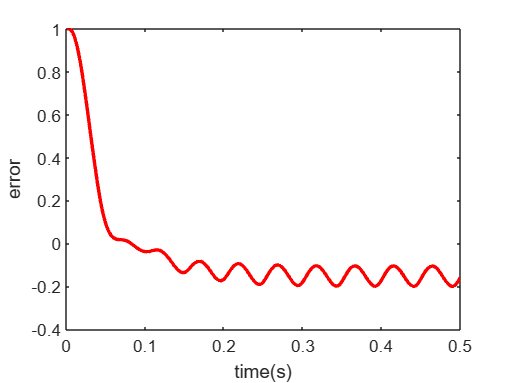

figure(2);
plot(time,yd-y,'r','linewidth',2);
xlabel('time(s)');ylabel('error');

## Chapter 3: Foundation of fuzzy Mathematics

### 3.1 Fuzzy set expression

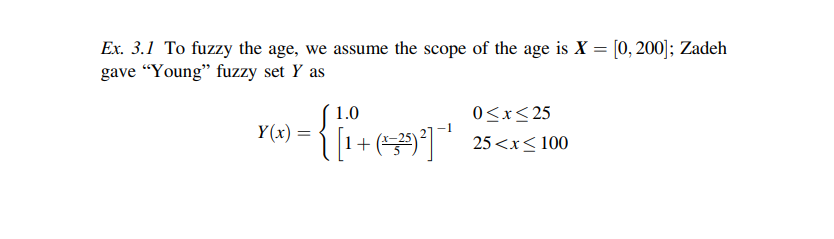

imshow(imread("fuzzy_age.png"));

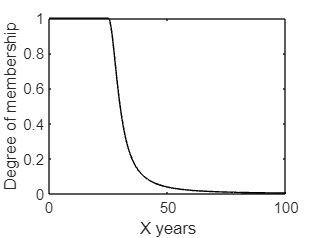


% Membership function for young people
clear all
close all

for k = 1:1001
    x(k) = (k-1)*0.1;
    if x(k) >= 0 & x(k)<= 25
        y(k) = 1.0;
    else
        y(k) = 1/(1 + ((x(k) - 25)/5)^2);
    end
end

plot(x,y,'k');
xlabel("X years");
ylabel('Degree of membership');

### 3.2 Typical membership functions

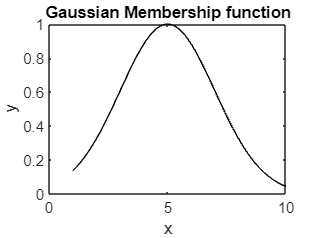

% Gaussian Membership function
x = 1:0.1:10;
c = 5;
delta = 2;
y = gaussmf(x,[delta c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('Gaussian Membership function');

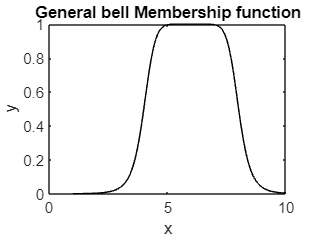


% General bell membership function

x = 1:0.1:10;
a = 2;
b = 4;
c = 6;
y = gbellmf(x,[a b c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('General bell Membership function');

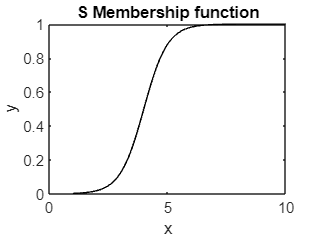



% S membership function

x = 1:0.1:10;
a = 2;
c = 4;
y = sigmf(x,[a c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('S Membership function');

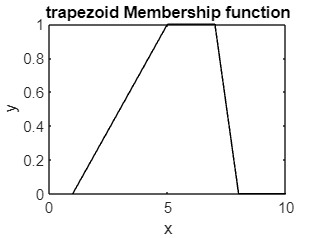


% trapezoid membership function

x = 1:0.1:10;
a = 1;
b = 5;
c = 7;
d = 8;
y = trapmf(x,[a b c d]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('trapezoid Membership function');

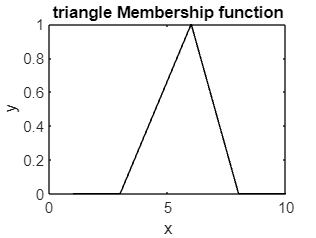


% Triangle membership function

x = 1:0.1:10;
a = 3;
b = 6;
c = 8;
y = trimf(x,[a b c]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('triangle Membership function');

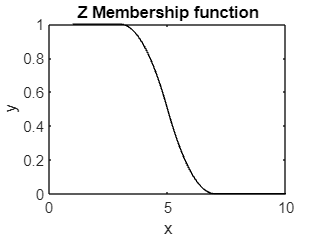


% Z membership function

x = 1:0.1:10;
a = 3;
b = 7;
y = zmf(x,[a b]);
plot(x,y,'k');
xlabel('x');ylabel('y');
title('Z Membership function');

### 3.3 Design of fuzzy system

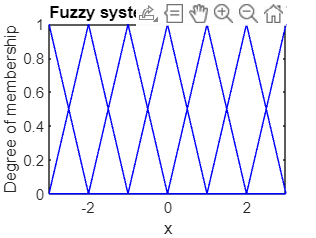

% To fuzzify a variable, we can use several fuzzy sets
% For example, to describe the error from big negative to big positive with
% 7 fuzzy sets, we define the error as e = {NB, NM, NS, ZO, PS, PM, PB}
% Use triangle MF and consider variable e varies in the range [-3,3]

% Define N+1 triangle membership function
clear all;
close all;

N = 6;
x = -3:0.01:3;

for i = 1:N+1
    f(i) = -3 + 6/N*(i-1);
end
% f = [-3 -2 -1 0 1 2 3]

u = trimf(x,[f(1),f(1),f(2)]);
figure(1);
plot(x,u,'b');
axis([-3 3 0 1])
hold on

for j = 2:N
    u = trimf(x,[f(j-1),f(j),f(j+1)]);
    plot(x,u,'b');
end

u = trimf(x,[f(N),f(N+1),f(N+1)]);
plot(x,u,'b');

xlabel('x');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF');

hold off

### 3.4 fuzzy matrix compound calculation

clear all;
close all;

A = [0.8 0.7
    0.5 0.3];
sz_A = size(A);

B = [0.2 0.4
    0.6 0.9];
sz_B = size(B);

% Compound of A and B
for i = 1:sz_A(1)
    for j = 1:sz_B(1)
        C(i,j) = max(min(A(i,:),B(:,j)'));
    end
end

'Compound of A and B'

ans = 'Compound of A and B'

C

C =     0.6000    0.7000
    0.3000    0.4000



% Compound of B and A
for i = 1:sz_B(1)
    for j = 1:sz_A(1)
        D(i,j) = max(min(B(i,:),A(:,j)'));
    end
end

'Compound of B and A'

ans = 'Compound of B and A'

D

D =     0.4000    0.3000
    0.6000    0.6000


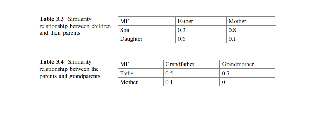


% The compound calculation of fuzzy matrix permits to compute the
% similarity between two elements when we have two matrices that describe the
% similarity between elements and they have the same elements in lines and columns

% Example

imshow(imread("similarity_relationship_matrices.png"));


% R is the similarity relationship between children and their parents
R = [0.2 0.8
    0.6 0.1];

% S is the similarity relationship between parents and grandparents
S = [0.5 0.7
    0.1 0];

% The similarity relationship between children and grandparents is
% described by the compound calculation between R and S

% Compound of R and S
sz_R = size(R);
sz_S = size(S);

for i = 1:sz_R(1)
    for j = 1:sz_S(1)
        RoS(i,j) = max(min(R(i,:),S(:,j)'));
    end
end

'Compound of R and S'

ans = 'Compound of R and S'

RoS

RoS =     0.2000    0.2000
    0.5000    0.6000


### 3.5 Fuzzy inference

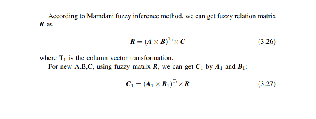

% Consider the rule "If A and B then C

clear all; close all

imshow(imread("fuzzy_inference.png"));


A = [0.5 1 0.1]';

B = [0.1 1 0.6];

C = [0.4 1];

% Compound of A and B

for i = 1:length(A)
    for j = 1:length(B)
        AoB(i,j) = min(A(i),B(j));
    end
end

'Compound between A and B'

ans = 'Compound between A and B'

AoB

AoB =     0.1000    0.5000    0.5000
    0.1000    1.0000    0.6000
    0.1000    0.1000    0.1000



% Column vector transformation
T1 = [];

for i = 1:length(A)
    T1 = [T1;AoB(i,:)'];
end

% Get fuzzy relation matrix R
for i = 1:length(T1)
    for j = 1:length(C)
        R(i,j) = min(T1(i),C(j));
    end
end

'Fuzzy relation matrix R'

ans = 'Fuzzy relation matrix R'

R

R =     0.1000    0.1000
    0.4000    0.5000
    0.4000    0.5000
    0.1000    0.1000
    0.4000    1.0000
    0.4000    0.6000
    0.1000    0.1000
    0.1000    0.1000
    0.1000    0.1000



% New matrices A1 and B1 and C1

A1 = [1 0.5 0.1]';

B1 = [0.1 0.5 1];

% Compound of A1 and B1

for i = 1:length(A1)
    for j = 1:length(B1)
        A1oB1(i,j) = min(A1(i),B1(j));
    end
end

'Compound between A1 and B1'

ans = 'Compound between A1 and B1'

A1oB1

A1oB1 =     0.1000    0.5000    1.0000
    0.1000    0.5000    0.5000
    0.1000    0.1000    0.1000



% raw vector transformation
T2 = [];

for i = 1:length(A1)
    T2 = [T2 A1oB1(i,:)];
end

% Get output C1
sz_R = size(R)

sz_R =      9     2


for i = 1:length(T2)
    for j = 1:sz_R(2)
        D(i,j) = min(T2(i),R(i,j));
        C1(j) = max(D(:,j));
    end
end

'Output C1'

ans = 'Output C1'

C1

C1 =     0.4000    0.5000



% so C1 = 0.4/c1 + 0.5/c2

## Chapter 4: Fuzzy Logic Control

### 4.1 Design of Fuzzy Logic Controller for height water tank

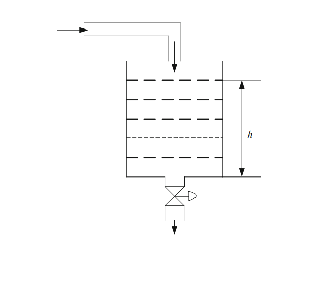

% Fuzzy control for a height level of water tank
clear all; close all; warning off

imshow(imread("height_level_water_tank.png"));

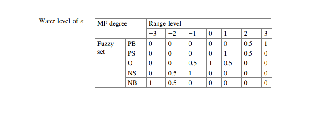


a = newfis('fuzz_tank');

%% (1) Fuzzify input and output

% Parameter of error e

imshow(imread("water_level_e.png"));

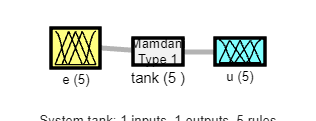


a = addvar(a,'input','e',[-3,3]);
a = addmf(a,'input',1,'NB','zmf',[-3,-1]);
a = addmf(a,'input',1,'NS','trimf',[-3,-1,1]);
a = addmf(a,'input',1,'Z','trimf',[-2,0,2]);
a = addmf(a,'input',1,'PS','trimf',[-1,1,3]);
a = addmf(a,'input',1,'PB','smf',[1,3]);

% Parameter of control u

imshow(imread("control_u.png"));

a = addvar(a,'output','u',[-4,4]);
a = addmf(a,'output',1,'NB','zmf',[-4,-1]);
a = addmf(a,'output',1,'NS','trimf',[-4,-2,1]);
a = addmf(a,'output',1,'Z','trimf',[-2,0,2]);
a = addmf(a,'output',1,'PS','trimf',[-1,2,4]);
a = addmf(a,'output',1,'BP','smf',[1 4]);

%% (2) Edit rule base

rulelist = [1 1 1 1
    2 2 1 1
    3 3 1 1
    4 4 1 1
    5 5 1 1];

a = addrule(a,rulelist);

% (3) Defuzzy

a1 = setfis(a,'DefuzzMethod','mom');

% Save to fuzzy filz "tank.fis"
writefis(a1,'tank');
a2 = readfis('tank');

% Plot system of tank and fuzzy system of input e and output u
figure(1)
plotfis(a2);

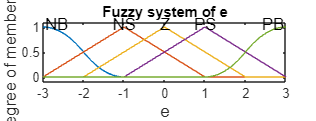

figure(2)
plotmf(a,'input',1);
title('Fuzzy system of e');

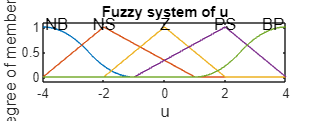

figure(3)
plotmf(a,'output',1);
title('Fuzzy system of u');


flag = 1

flag = 1

ans = 5×34 char array
    '1. If (e is NB) then (u is NB) (1)'
    '2. If (e is NS) then (u is NS) (1)'
    '3. If (e is Z) then (u is Z) (1)  '
    '4. If (e is PS) then (u is PS) (1)'
    '5. If (e is PB) then (u is BP) (1)'


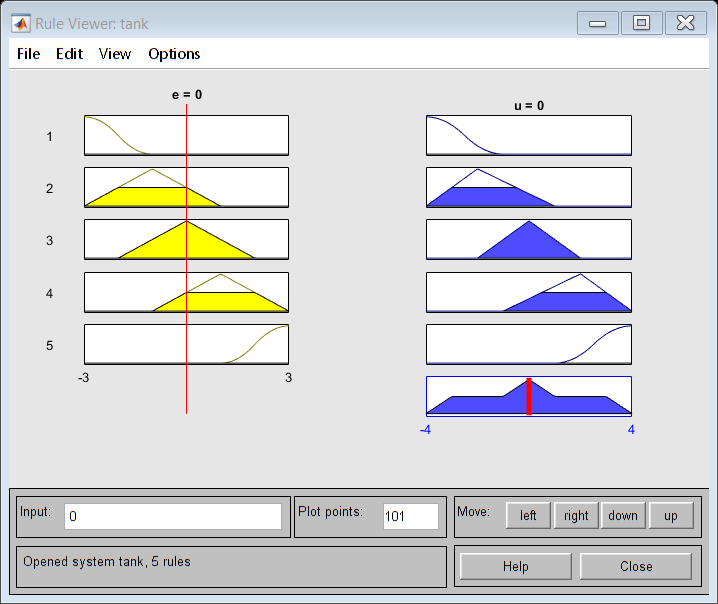

if flag == 1
    showrule(a) % Show fuzzy rule base
    ruleview('tank'); % Dynamic Simulation
end


disp('—————————————————————————————————————————————————————');

—————————————————————————————————————————————————————


disp(' fuzzy controller table:e=[-3,+3],u=[-4,+4] ');

 fuzzy controller table:e=[-3,+3],u=[-4,+4] 


disp('—————————————————————————————————————————————————————');

—————————————————————————————————————————————————————



for i = 1:7
    e(i) = i-4;
    Ulist(i) = evalfis([e(i)],a2);
end
Ulist = round(Ulist)

Ulist =     -4    -2    -2     0     2     2     4


### 4.2 Design of Fuzzy Logic Controller for Washing machine

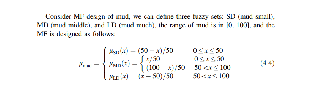

% Design a fuzzy controller with 2 inputs and 1 output
clear all; close all; warning off

% (1) define of membership functions

%% MF of mud

imshow(imread("MF_mud.png"));

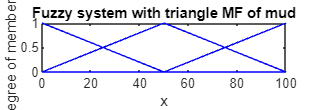


N = 2;

x = 0:0.1:100;

for i = 1:N+1
    f(i) = 100/N*(i-1);
end

% f = [0 50 100]

u = trimf(x,[f(1),f(1),f(2)]);
figure(1);
plot(x,u,'b');
axis([0 100 0 1])
hold on

for j = 2:N
    u = trimf(x,[f(j-1),f(j),f(j+1)]);
    plot(x,u,'b');
end

u = trimf(x,[f(N),f(N+1),f(N+1)]);
plot(x,u,'b');

xlabel('x');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF of mud');

hold off

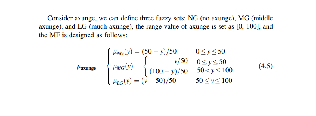


%% MF of axunge

imshow(imread("MF_axunge.png"));


N = 2;

x = 0:0.1:100;


for i = 1:N+1
    f(i) = 100/N*(i-1);
end
f

f =      0    50   100


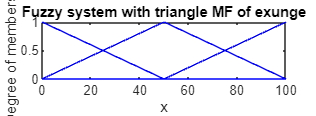

% f = [0 50 100]

u = trimf(x,[f(1),f(1),f(2)]);
figure(1);
plot(x,u,'b');
axis([0 100 0 1])
hold on

for j = 2:N
    u = trimf(x,[f(j-1),f(j),f(j+1)]);
    plot(x,u,'b');
end

u = trimf(x,[f(N),f(N+1),f(N+1)]);
plot(x,u,'b');

xlabel('x');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF of exunge');

hold off

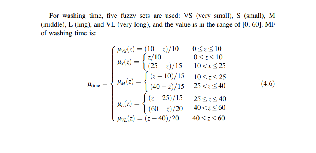


%% MF of washing time

imshow(imread("MF_washing_time.png"));

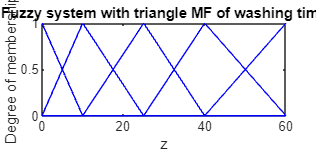


z = 0:0.1:60;

u = trimf(z,[0 0 10]);
figure(1);
plot(z,u,'b');

hold on

u = trimf(z,[0 10 25]);
plot(z,u,'b');

u = trimf(z,[10 25 40]);
plot(z,u,'b');

u = trimf(z,[25 40 60]);
plot(z,u,'b');

u = trimf(z,[40 60 60]);
plot(z,u,'b');

xlabel('z');
ylabel('Degree of membership');
title('Fuzzy system with triangle MF of washing time');
axis([0 60 0 1]);

hold off

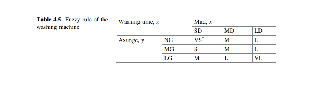


 % (2) fuzzy rule of the washing machine in respect of mud and axunge
imshow(imread("fuzzy_rule_washing_time_machine.png"));


% (3) fuzzy rule activation of the washing machine
imshow(imread("fuzzy_rule_activation.png"));

% Simulation of washing time

% Fuzzy control for a washing time

a = newfis('fuzz_wash');

%% (1) Fuzzify inputs and output

% Parameter of mud

a = addvar(a,'input','x',[0 100]);
a = addmf(a,'input',1,'SD','trimf',[0 0 50]);
a = addmf(a,'input',1,'MD','trimf',[0 50 100]);
a = addmf(a,'input',1,'LD','trimf',[50 100 100]);

% Parameter of exauge

a = addvar(a,'input','y',[0 100]);
a = addmf(a,'input',2,'NG','trimf',[0 0 50]);
a = addmf(a,'input',2,'MG','trimf',[0 50 100]);
a = addmf(a,'input',2,'LG','trimf',[50 100 100]);

% Parameter of washing time

a = addvar(a,'output','z',[0 60]);
a = addmf(a,'output',1,'VS','trimf',[0 0 10]);
a = addmf(a,'output',1,'S','trimf',[0 10 25]);
a = addmf(a,'output',1,'M','trimf',[10 25 40]);
a = addmf(a,'output',1,'L','trimf',[25 40 60]);
a = addmf(a,'output',1,'VL','trimf',[40 60 60]);

%% (2) Edit rule base

rulelist=[1 1 1 1 1; 
1 2 3 1 1;
1 3 4 1 1;
2 1 2 1 1;
2 2 3 1 1;
2 3 4 1 1;
3 1 3 1 1;
3 2 4 1 1;
3 3 5 1 1];

a = addrule(a,rulelist);
showrule(a) % Show fuzzy rule base

ans = 9×48 char array
    '1. If (x is SD) and (y is NG) then (z is VS) (1)'
    '2. If (x is SD) and (y is MG) then (z is M) (1) '
    '3. If (x is SD) and (y is LG) then (z is L) (1) '
    '4. If (x is MD) and (y is NG) then (z is S) (1) '
    '5. If (x is MD) and (y is MG) then (z is M) (1) '
    '6. If (x is MD) and (y is LG) then (z is L) (1) '
    '7. If (x is LD) and (y is NG) then (z is M) (1) '
    '8. If (x is LD) and (y is MG) then (z is L) (1) '
    '9. If (x is LD) and (y is LG) then (z is VL) (1)'


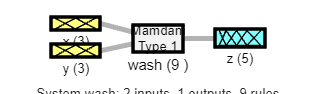


% (3) Defuzzy

a1 = setfis(a,'DefuzzMethod','mom');

% Save to fuzzy file "wash.fis"
writefis(a1,'wash');
a2 = readfis('wash');

% Plot system of washing time and fuzzy system of inputs mud and axunge and
% output washing time
figure(1)
plotfis(a2);

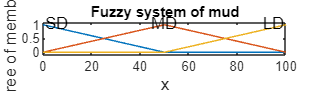

figure(2)
plotmf(a,'input',1);
title('Fuzzy system of mud');

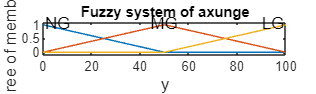

figure(3)
plotmf(a,'input',2);
title('Fuzzy system of axunge');

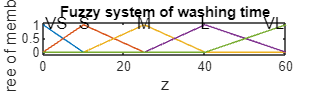

figure(4)
plotmf(a,'output',1);
title('Fuzzy system of washing time');


x = 60;
y = 70;
evalfis([x,y],a2)

ans = 24.9000

### 4.3 Design of Fuzzy Logic Controller for PI controller

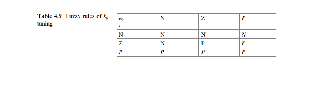

% Design a fuzzy controller for PI controller with 2 inputs and 2 outputs
% (kp and ki)
clear all; close all;warning off

%% fuzzy rules for kp

imshow(imread("fuzzy_rules_kp.png"));


%% fuzzy rules for ki

imshow(imread("fuzzy_rules_ki.png"));

% Simulation of PI controller

a = newfis('fuzz_wash');

%% (1) Fuzzify inputs and output

% Parameter of error

a = addvar(a,'input','e',[-1 1]);
a = addmf(a,'input',1,'N','zmf',[-1 -1/3]);
a = addmf(a,'input',1,'Z','trimf',[-2/3 0 2/3]);
a = addmf(a,'input',1,'P','smf',[1/3 1]);

% Parameter of error change

a = addvar(a,'input','ec',[-1 1]);
a = addmf(a,'input',2,'N','zmf',[-1 -1/3]);
a = addmf(a,'input',2,'Z','trimf',[-2/3 0 2/3]);
a = addmf(a,'input',2,'P','smf',[1/3 1]);

% Parameter of kp

a = addvar(a,'output','kp',1/3 * [-10 10]);
a = addmf(a,'output',1,'N','zmf',1/3 * [-10 -3]);
a = addmf(a,'output',1,'Z','trimf',1/3 * [-5 0 5]);
a = addmf(a,'output',1,'P','smf',1/3 * [3 10]);

% Parameter of ki

a = addvar(a,'output','ki',1/30 * [-3 3]);
a = addmf(a,'output',2,'N','zmf',1/30 * [-3 -1]);
a = addmf(a,'output',2,'Z','trimf',1/30 * [-2 0 2]);
a = addmf(a,'output',2,'P','smf',1/3 * [1 3]);

%% (2) Edit rule base

rulelist=[1 1 1 2 1 1;
1 2 1 2 1 1;
1 3 1 2 1 1;
2 1 1 3 1 1;
2 2 3 3 1 1;
2 3 3 3 1 1;
3 1 3 2 1 1;
3 2 3 2 1 1;
3 3 3 2 1 1];

a = addrule(a,rulelist);
showrule(a) % Show fuzzy rule base

ans = 9×56 char array
    '1. If (e is N) and (ec is N) then (kp is N)(ki is Z) (1)'
    '2. If (e is N) and (ec is Z) then (kp is N)(ki is Z) (1)'
    '3. If (e is N) and (ec is P) then (kp is N)(ki is Z) (1)'
    '4. If (e is Z) and (ec is N) then (kp is N)(ki is P) (1)'
    '5. If (e is Z) and (ec is Z) then (kp is P)(ki is P) (1)'
    '6. If (e is Z) and (ec is P) then (kp is P)(ki is P) (1)'
    '7. If (e is P) and (ec is N) then (kp is P)(ki is Z) (1)'
    '8. If (e is P) and (ec is Z) then (kp is P)(ki is Z) (1)'
    '9. If (e is P) and (ec is P) then (kp is P)(ki is Z) (1)'


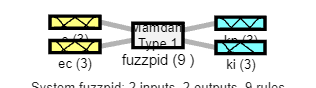

ruleview fuzzpid

% (3) Defuzzy

a1 = setfis(a,'DefuzzMethod','mom');

% Save to fuzzy file "fuzzpid.fis"
writefis(a1,'fuzzpid');
a2 = readfis('fuzzpid');

% Plot system of PI and fuzzy system of inputs error and change of error and
% 2 outputs kp and ki
figure(1)
plotfis(a2);

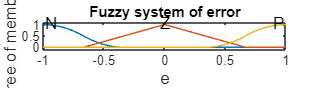

figure(2)
plotmf(a,'input',1);
title('Fuzzy system of error');

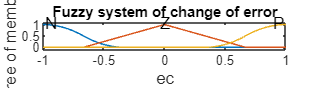

figure(3)
plotmf(a,'input',2);
title('Fuzzy system of change of error');

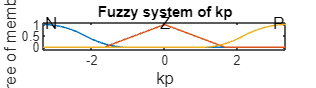

figure(4)
plotmf(a,'output',1);
title('Fuzzy system of kp');

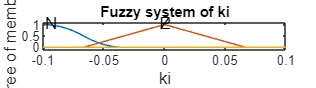

figure(5)
plotmf(a,'output',2);
title('Fuzzy system of ki');

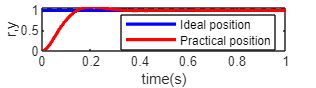


%% Fuzzy PI control
warning off

ts = 0.001; % sampling time
sys = tf(133, [1,25,0]); % transfer function of plant G(s) = 133/(s^2 + 25s)
dsys = c2d(sys,ts,'z');
[num,den] = tfdata(dsys,'v');
u_1 = 0;u_2 = 0;
y_1 = 0;y_2 = 0;
e_1 = 0;ec_1 = 0;ei = 0;
kp0 = 0;ki0 = 0;

for k = 1:1000
    time(k) = k*ts;
    yd(k) = 1;
    % fuzzy inference to tuning PI
    k_pid = evalfis([e_1,ec_1],a2);
    kp(k) = kp0 + k_pid(1);
    ki(k) = ki0 + k_pid(2);
    u(k) = kp(k)*e_1 + ki(k)*ei;
    y(k) = -den(2)*y_1 - den(3)*y_2 + num(2)*u_1 + num(3)*u_2;
    e(k) = yd(k) - y(k);

    % Actualize of input and output parameters of transfer function
    u_2 = u_1; u_1 = u(k);
    y_2 = y_1; y_1 = y(k);
    ei = ei + e(k)*ts; % Calculating of I action
    ec(k) = e(k) - e_1;
    e_1 = e(k);
    ec_1 = ec(k);
end

% Plot step response
figure(1);
plot(time,yd,'b',time,y,'r','linewidth',2);
xlabel('time(s)');ylabel('r,y');
legend('Ideal position','Practical position')

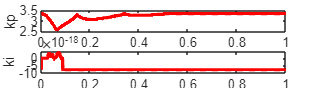

figure(2);
subplot(211);
plot(time,kp,'r','linewidth',2);
xlabel('time(s)');ylabel('kp');
subplot(212);
plot(time,ki,'r','linewidth',2);
xlabel('time(s)');ylabel('ki');

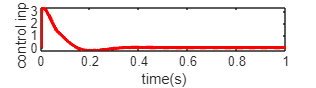


clf

figure(3);
plot(time,u,'r','linewidth',2);
xlabel('time(s)');ylabel('control input');

## Chapter 5: Fuzzy Takagi-Sugeno (T-S) Modeling and control

### 5.1 Simulation of a simple T-S type fuzzy model

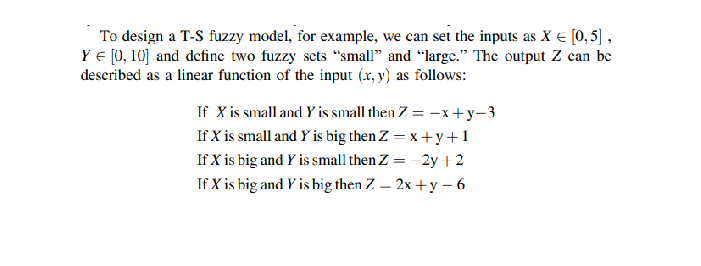

clear all; close all; warning off

% The fuzzy Takagi-Sugeno model to design
imshow(imread("design_simple_TS_fuzzy_model.png"));


% Build architucture of TS fuzzy model

ts2 = newfis('ts2','sugeno');
ts2 = addvar(ts2,'input', 'X',[0 5]);
ts2 = addmf(ts2,'input',1,'little','gaussmf',[1.8 0]);
ts2 = addmf(ts2,'input',1,'big','gaussmf',[1.8 5]);
ts2 = addvar(ts2,'input', 'Y',[0 10]);
ts2 = addmf(ts2,'input',2,'little','gaussmf',[4.4 0]);
ts2 = addmf(ts2,'input',2,'big','gaussmf',[4.4 10]);
ts2 = addvar(ts2,'output', 'z',[-3 15]);
ts2 = addmf(ts2,'output',1,'first area','linear',[-1 1 -3]);
ts2 = addmf(ts2,'output',1,'second area','linear',[1 1 1]);
ts2 = addmf(ts2,'output',1,'third area','linear',[0 -2 2]);
ts2 = addmf(ts2,'output',1,'fourth area','linear',[2  1 -6]);

% Rules
rulelist = [1 1 1 1 1
    1 2 2 1 1
    2 1 3 1 1
    2 2 4 1 1];
ts2 = addrule(ts2,rulelist);
showrule(ts2)

ans = 4×64 char array
    '1. If (X is little) and (Y is little) then (z is first area) (1)'
    '2. If (X is little) and (Y is big) then (z is second area) (1)  '
    '3. If (X is big) and (Y is little) then (z is third area) (1)   '
    '4. If (X is big) and (Y is big) then (z is fourth area) (1)     '


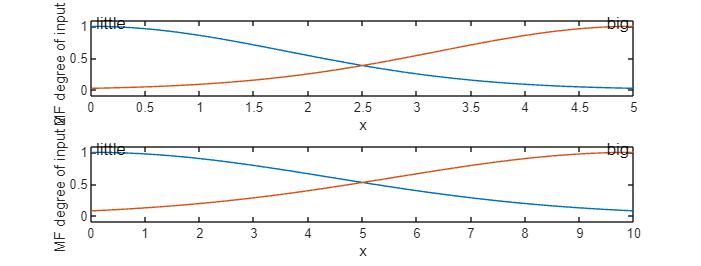


% Plot membership function of inputs

figure(1);
subplot(211);
plotmf(ts2,'input',1);
xlabel('x');
ylabel('MF degree of input 1');
subplot(212);
plotmf(ts2,'input',2);
xlabel('x');
ylabel('MF degree of input 2');

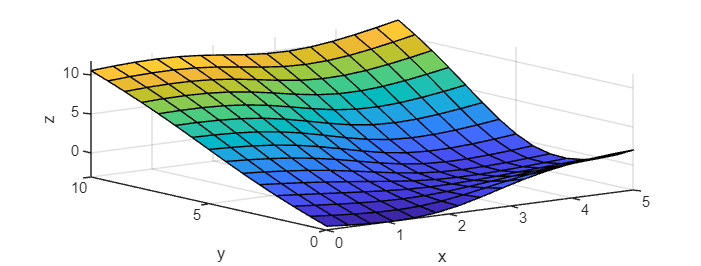


clf
figure(2);
gensurf(ts2);
xlabel('x');
ylabel('y');
zlabel('z');

### 5.2 Fuzzy T-S modeling and control based on Linear matrix inequality (LMI)

#### 5.2.1 Controller gain based on LMI for control of Inverted pendulum with 2 rules

clear all;close all;

% Physical constant of inverted pendulum
g = 9.8; % constant gravity in earth (m/s2)
m = 2; % mass of cart (kg)
M = 8; % mass of pendulum (kg)
l = 0.5; % half of length of pendulum (m)
a = 1/(M+m);
beta = cos(88*pi/180);

% State space representation for 2 rules selected

% rule 1: if x1 is about 0 then dx/dt = A1*x + B1*u
% rule 2: if abs(x1) is about pi/2 then dx/dt = A2*x + B2*u

beta=cos(88*pi/180);
a1=4*l/3-a*m*l;
A1=[0 1;g/a1 0];
B1=[0 ;-a/a1];
a2=4*l/3-a*m*l*beta^2;
A2=[0 1;2*g/(pi*a2) 0];
B2=[0;-a*beta/a2];


% LMI design with solution of Lyapunov equation
% Should install Robust Control Toolbox and  YALMIP toolbox following the
% url: https://yalmip.github.io/tutorial/installation/

Q = sdpvar(2,2);
V1 = sdpvar(1,2);
V2 = sdpvar(1,2);

L1=Q*A1'+A1*Q+V1'*B1'+B1*V1;
L2=Q*A2'+A2*Q+V2'*B2'+B2*V2;
L3=Q*A1'+A1*Q+Q*A2'+A2*Q+V2'*B1'+B1*V2+V1'*B2'+B2*V1;
F = [L1<=0];
F = [F,L2<=0];
F = [F ,L3<=0];
F = [F,Q>=0];

solvesdp(F); %To get Q,V1,V2


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.083653
     2                        0.044254
     3                        0.044254
     4                    2.198866e-03
     5                       -0.022577

 Result:  best value of t:    -0.022577
          f-radius saturation:  0.000% of R =  1.00e+09
 
#############################################################
You are using LMILAB. Please don't use LMILAB with YALMIP
https://yalmip.github.io/solver/lmilab/
 
Install a better SDP solver
https://yalmip.github.io/allsolvers/
 
To get rid of this message, edit calllmilab.m  
(but don't expect support when things do not work,
YALMIP + LMILAB => No support)
#############################################################



Q = double(Q);
V1 = double(V1);
V2 = double(V2);
P = inv(Q);
K1 = V1*P

K1 = 1.0e+03 *

    1.2432    0.3594


K2 = V2*P

K2 = 1.0e+03 *

    2.6328    0.7738


save K_file K1 K2

% membership function design

clear all;close all;
L1 =  -pi/2;
L2 = pi/2;
L = L2 - L1;
h = pi/2;
N = L/h;
T = 0.01;
x = L1:T:L2

x =    -1.5708   -1.5608   -1.5508   -1.5408   -1.5308   -1.5208   -1.5108   -1.5008   -1.4908   -1.4808   -1.4708   -1.4608   -1.4508   -1.4408   -1.4308   -1.4208   -1.4108   -1.4008   -1.3908   -1.3808   -1.3708   -1.3608   -1.3508   -1.3408   -1.3308   -1.3208   -1.3108   -1.3008   -1.2908   -1.2808   -1.2708   -1.2608   -1.2508   -1.2408   -1.2308   -1.2208   -1.2108   -1.2008   -1.1908   -1.1808   -1.1708   -1.1608   -1.1508   -1.1408   -1.1308   -1.1208   -1.1108   -1.1008   -1.0908   -1.0808


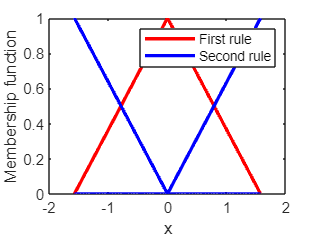


for i = 1:N+1
    e(i) = L1 + L/N*(i-1);
end

u = trimf(x,[e(1) e(2) e(3)]); % the middle MF
plot(x,u,'r','LineWidth',2);

for j=1:N
    if j == 1
        u = trimf(x,[e(1) e(1) e(2)]); % the first MF
    elseif j == N
        u = trimf(x,[e(N) e(N+1) e(N+1)]); % the last MF
    end
    hold on
    plot(x,u,'b','LineWidth',2);
end
xlabel('x');ylabel('Membership function');
legend('First rule','Second rule')

#### 5.2.2 Controller gain based on LMI for control of Inverted pendulum with 4 rules

clear all;close all;

% Physical constant of inverted pendulum
g = 9.8; % constant gravity in earth (m/s2)
m = 2; % mass of cart (kg)
M = 8; % mass of pendulum (kg)
l = 0.5; % half of length of pendulum (m)
a = 1/(M+m);
beta = cos(88*pi/180);

% State space representation for 4 rules selected

% rule 1: if x1 is about 0 then dx/dt = A1*x + B1*u
% rule 2: if abs(x1) < pi/2 then dx/dt = A2*x + B2*u
% rule 3: if abs(x1) > pi/2 then dx/dt = A3*x + B3*u
% rule 4: if abs(x1) is about pi then dx/dt = A4*x + B4*u

beta=cos(88*pi/180);
a1=4*l/3-a*m*l;
A1=[0 1;g/a1 0];
B1=[0 ;-a/a1];
a2=4*l/3-a*m*l*beta^2;
A2=[0 1;2*g/(pi*a2) 0];
B2=[0;-a*beta/a2];
a3=pi*a2;
A3=[0 1;2*g/a3 0];
B3=[0 ;a*beta*pi/a3];
a4=4*l/3-a*m*l;
A4=[0 1;0 0];
B4=[0;a/a4];

% LMI design with solution of Lyapunov equation
% Should install Robust Control Toolbox and  YALMIP toolbox following the
% url: https://yalmip.github.io/tutorial/installation/

Q = sdpvar(2,2);
V1 = sdpvar(1,2);
V2 = sdpvar(1,2);
V3 = sdpvar(1,2);
V4 = sdpvar(1,2);

L1=Q*A1'+A1*Q+V1'*B1'+B1*V1;
L2=Q*A2'+A2*Q+V2'*B2'+B2*V2;
L3=Q*A3'+A3*Q+V3'*B3'+B3*V3;
L4=Q*A4'+A4*Q+V4'*B4'+B4*V4;
L5=Q*A1'+A1*Q+Q*A2'+A2*Q+V2'*B1'+B1*V2+V1'*B2'+B2*V1;
L6=Q*A3'+A3*Q+Q*A4'+A4*Q+V4'*B3'+B3*V4+V3'*B4'+B4*V3;
F = [L1<=0];
F = [F,L2<=0];
F = [F ,L3<=0];
F = [F ,L4<=0];
F = [F ,L5<=0];
F = [F ,L6<=0];
F = [F,Q>=0];

solvesdp(F); %To get Q,V1,V2,V3,V4


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.075650
     2                        0.042280
     3                        0.042280
     4                        0.012358
     5                       -0.011921

 Result:  best value of t:    -0.011921
          f-radius saturation:  0.000% of R =  1.00e+09
 
#############################################################
You are using LMILAB. Please don't use LMILAB with YALMIP
https://yalmip.github.io/solver/lmilab/
 
Install a better SDP solver
https://yalmip.github.io/allsolvers/
 
To get rid of this message, edit calllmilab.m  
(but don't expect support when things do not work,
YALMIP + LMILAB => No support)
#############################################################



Q = double(Q);
V1 = double(V1);
V2 = double(V2);
V3 = double(V3);
V4 = double(V4);
P = inv(Q);
K1 = V1*P

K1 = 1.0e+03 *

    1.7481    0.5154


K2 = V2*P

K2 = 1.0e+03 *

    3.3341    0.9891


K3 = V3*P

K3 = 1.0e+03 *

   -3.2455   -0.9911


K4 = V4*P

K4 = 1.0e+03 *

   -1.6500   -0.5154


save K_file2 K1 K2 K3 K4

% membership function design

L1 =  -pi;
L2 = pi;
L = L2 - L1;
h = pi/2;
N = L/h;
T = 0.01;
x = L1:T:L2

x =    -3.1416   -3.1316   -3.1216   -3.1116   -3.1016   -3.0916   -3.0816   -3.0716   -3.0616   -3.0516   -3.0416   -3.0316   -3.0216   -3.0116   -3.0016   -2.9916   -2.9816   -2.9716   -2.9616   -2.9516   -2.9416   -2.9316   -2.9216   -2.9116   -2.9016   -2.8916   -2.8816   -2.8716   -2.8616   -2.8516   -2.8416   -2.8316   -2.8216   -2.8116   -2.8016   -2.7916   -2.7816   -2.7716   -2.7616   -2.7516   -2.7416   -2.7316   -2.7216   -2.7116   -2.7016   -2.6916   -2.6816   -2.6716   -2.6616   -2.6516


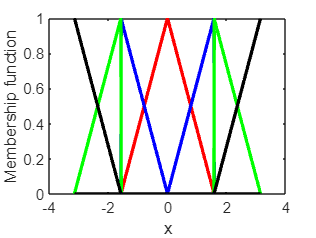


for i = 1:N+1
    e(i) = L1 + L/N*(i-1);
end

figure(2)

h1 = trimf(x,[e(2) e(3) e(4)]); % rule1: x1 is to zero
plot(x,h1,'r','LineWidth',2);

hold on

h2 = trimf(x,[e(2) e(2) e(3)]); % rule2 : x1 is to -pi/2 but higher
plot(x,h2,'b','LineWidth',2);

h2 = trimf(x,[e(3) e(4) e(4)]); % rule2 : x1 is to pi/2 but smaller
plot(x,h2,'b','LineWidth',2);

h3 = trimf(x,[e(1) e(2) e(2)]); % rule3 : x1 is to -pi/2 but smaller
plot(x,h3,'g','LineWidth',2);

h3 = trimf(x,[e(4) e(4) e(5)]); % rule3 : x1 is to pi/2 but higher
plot(x,h3,'g','LineWidth',2);

h4 = trimf(x,[e(1) e(1) e(2)]); % rule4 : x1 is to -pi
plot(x,h4,'k','LineWidth',2);

h4 = trimf(x,[e(4) e(5) e(5)]); % rule4 : x1 is to pi
plot(x,h4,'k','LineWidth',2);

hold off


xlabel('x');ylabel('Membership function');

#### 5.2.3 Find optimal value for Linear matrix inequality using YALMIP Toolbox

% Simulation example of YALMIP Toolbox
A = [-2.548 9.1 0
    1 -1 1
    0 -14.2 0];
B = [1 0 0; 0 1 0; 0 0 1];
F = sdpvar(3,3);
P = 1000000*eye(3);
FAI = (A' + F'*B')*P + P*(A+B*F);
L = [FAI <= 0];
solvesdp(L);


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
* switching to QR
     1                    -9.900495e+08

 Result:  best value of t: -9.900495e+08
          f-radius saturation:  99.005% of R =  1.00e+09
 
#############################################################
You are using LMILAB. Please don't use LMILAB with YALMIP
https://yalmip.github.io/solver/lmilab/
 
Install a better SDP solver
https://yalmip.github.io/allsolvers/
 
To get rid of this message, edit calllmilab.m  
(but don't expect support when things do not work,
YALMIP + LMILAB => No support)
#############################################################


F = double(F)

F =  -492.4768   -5.0500         0
   -5.0500 -494.0248    6.6000
         0    6.6000 -495.0248


## Chapter 6: Adaptive Fuzzy control

### 6.1 One Dimension function Approximation using Universal approximation theorem 

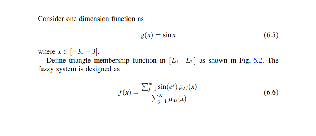

clear all;close all;

% One dimension function approximation
imshow(imread("one_dimension_function_approximation.png"));

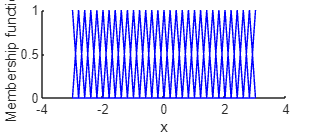


% N = 30 
L1 = -3; L2 = 3; % x is from [L1,L2]

L = L2 - L1; % Length of interval

h = 0.2; % the approximation accuracy of fuzzy system
N = L/h + 1; % number of fuzzy sets
T = 0.01; % sampling time

x = L1:T:L2;

for i = 1:N
    e(i) = L1+L/(N-1)*(i-1);
end

c=0;d=0;

clf
for j = 1:N
    if j == 1
        u = trimf(x,[e(1),e(1),e(2)]); % First MF
    elseif j == N
        u = trimf(x,[e(N-1),e(N),e(N)]); % last MF
    else
        u = trimf(x,[e(j-1) e(j) e(j+1)]);
    end
    hold on
    plot(x,u,'b');
    c = c + sin(e(j))*u;
    d = d + u;
end
xlabel('x');ylabel('Membership function');
hold off

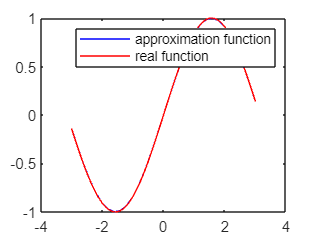


for k = 1:L/T+1
    f(k) = c(k)/d(k);
end

clf
y = sin(x);
figure(2)
plot(x,f,'b',x,y,'r');
legend('approximation function','real function');

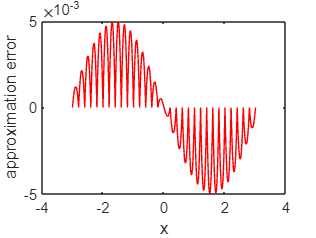


clf
figure(3)
plot(x,f-y,'r');
xlabel('x');ylabel('approximation error')

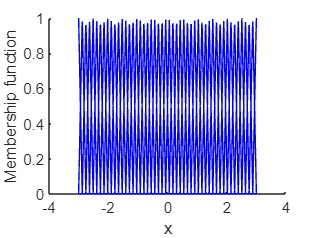


% N = 50
L1 = -3; L2 = 3; % x is from [L1,L2]

L = L2 - L1; % Length of interval

h = 0.1224; % the approximation accuracy of fuzzy system
N = 50; % number of fuzzy sets
T = 0.01; % sampling time

x = L1:T:L2;

for i = 1:N
    e(i) = L1+L/(N-1)*(i-1);
end

c=0;d=0;

clf
for j = 1:N
    if j == 1
        u = trimf(x,[e(1),e(1),e(2)]); % First MF
    elseif j == N
        u = trimf(x,[e(N-1),e(N),e(N)]); % last MF
    else
        u = trimf(x,[e(j-1) e(j) e(j+1)]);
    end
    hold on
    plot(x,u,'b');
    c = c + sin(e(j))*u;
    d = d + u;
end
xlabel('x');ylabel('Membership function');
hold off

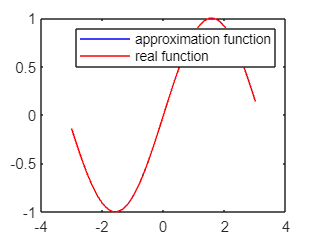


for k = 1:L/T+1
    f(k) = c(k)/d(k);
end

clf
y = sin(x);
figure(2)
plot(x,f,'b',x,y,'r');
legend('approximation function','real function');

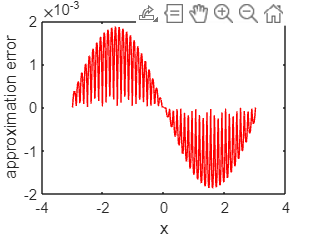


clf
figure(3)
plot(x,f-y,'r');
xlabel('x');ylabel('approximation error')

### 6.2 Two Dimension function Approximation using Universal approximation theorem

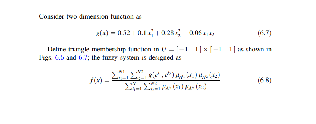

clear all;close all;

% One dimension function approximation
imshow(imread("two_dimension_function_approximation.png"));

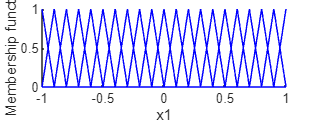


% N1 = 11 & N2 = 11

T = 0.1; % sampling time

L1 = -1; L2 = 1; % x is from [L1,L2]

L = L2 - L1; % Length of interval

x1 = L1:T:L2;
x2 = L1:T:L2;

h = 0.1; % the approximation accuracy of fuzzy system
N = L/h + 1; % number of fuzzy sets

for i = 1:N
    for j = 1:N
        e1(i) = L1+L/(N-1)*(i-1);
        e2(j) = L1+L/(N-1)*(j-1);
        gx(i,j) = 0.52 + 0.1*e1(i)^2 + 0.28*e2(j)^2 - 0.06*e1(i)*e2(j); % function to approximate
    end
end

cf=zeros(L/T+1);df=zeros(L/T + 1);

clf
for m = 1:N
    if m == 1
        u1 = trimf(x1,[e1(1),e1(1),e1(2)]); % First MF
    elseif m == N
        u1 = trimf(x1,[e1(N-1),e1(N),e1(N)]); % last MF
    else
        u1 = trimf(x1,[e1(m-1) e1(m) e1(m+1)]);
    end
    figure(1);
    hold on
    plot(x1,u1,'b');
end
xlabel('x1');ylabel('Membership function');
hold off

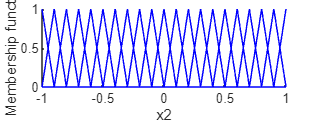


clf
for m = 1:N
    if m == 1
        u1 = trimf(x1,[e1(1),e1(1),e1(2)]); % First MF
    elseif m == N
        u1 = trimf(x1,[e1(N-1),e1(N),e1(N)]); % last MF
    else
        u1 = trimf(x1,[e1(m-1) e1(m) e1(m+1)]);
    end

for n = 1:N
    if n == 1
        u2 = trimf(x2,[e2(1),e2(1),e2(2)]); % First MF
    elseif n == N
        u2 = trimf(x2,[e2(N-1),e2(N),e2(N)]); % last MF
    else
        u2 = trimf(x2,[e2(n-1) e2(n) e2(n+1)]);
    end
    figure(2);
    hold on
    plot(x2,u2,'b');

xlabel('x2');ylabel('Membership function');
hold off

for i = 1:L/T+1
    for j = 1:L/T+1
        d = df(i,j) + u1(i)*u2(j);
        df(i,j)=d;
        c = cf(i,j) + gx(m,n)*u1(i)*u2(j);
        cf(i,j) = c;
    end
end
end
end

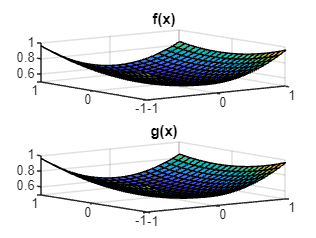


for i = 1:L/T+1
    for j = 1:L/T+1
        f(i,j) = cf(i,j)/df(i,j);
        y(i,j) = 0.52 + 0.1*x1(i)^2 + 0.28*x2(j)^2 - 0.06*x1(i)*x2(j); 
    end
end

clf
figure(3)
subplot(211);
surf(x1,x2,f);
title('f(x)');
subplot(212);
surf(x1,x2,y);
title('g(x)');

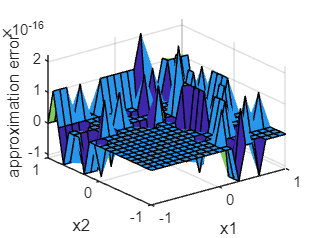


clf
figure(4)
surf(x1,x2,f-y);
xlabel('x1');ylabel('x2');zlabel('approximation error');

### 6.3 Adaptive fuzzy controller design

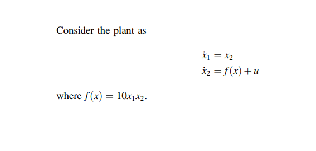

clear all;close all;

% The plant to control
imshow(imread("plant_to_control_with_adaptive_fuzzy_logic_controller.png"));

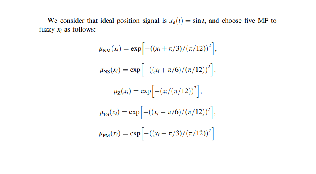


% Membership function design
imshow(imread("adaptive_fuzzy_controller_rules.png"));

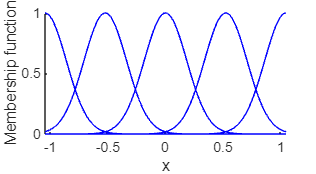


L1 = -pi/3; L2 = pi/3; % x is from [L1,L2]

L = L2 - L1; % Length of interval

T = L*1/1000; % sampling time

x = L1:T:L2;

clf

figure(1);

for i = 1:5
    gs = -[(x + pi/3 - (i-1)*pi/6) / (pi/12)].^2;
    u =exp(gs);
    hold on
    plot(x,u,'b');
end
xlabel('x');ylabel('Membership function')
hold off

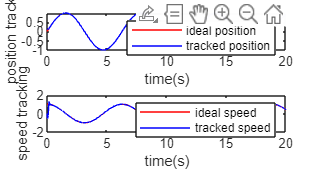

% Plot of position and speed tracking and the system function and the
% approximation of system function

clf
% To make plots first run simulink file
% Simulation_adaptive_fuzzy_logic_controller.mdl
figure(1);
subplot(211);
plot(out.t,out.x(:,1),'r',out.t,out.x(:,2),'b');
xlabel('time(s)');ylabel('position tracking');
legend('ideal position','tracked position');
subplot(212);
plot(out.t,cos(out.t),'r',out.t,out.x(:,3),'b');
xlabel('time(s)');ylabel('speed tracking');
legend('ideal speed','tracked speed');

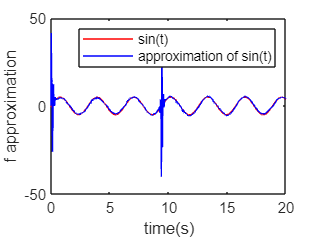


clf
figure(2);
plot(out.t,out.f(:,1),'r',out.t,out.f(:,3),'b');
xlabel('time(s)');ylabel('f approximation');
legend('sin(t)','approximation of sin(t)');

### 6.4 Adaptive fuzzy control based on fuzzy system compensator for 2 joint manipulator

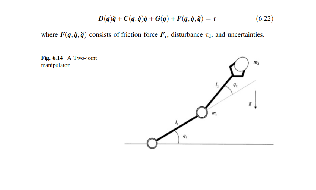

clear all;close all; 

% The plant to control
imshow(imread("2_joint_manipulator.png"));

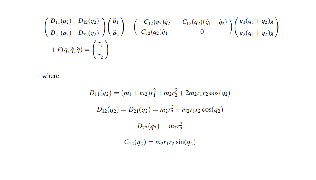

imshow(imread("2_joint_manipulator_equations.png"));

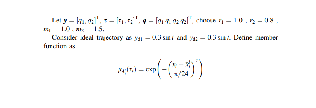

imshow(imread("2_joint_manipulator_constants.png"));

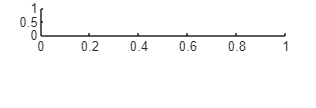


clf
figure(1);
subplot(211);

plot(out.t,out.yd1(:,1),'r',out.t,out.y(:,1),'b');

Unable to resolve the name 'out.t'.

xlabel('time(s)');ylabel('Angle tracking of first link');
subplot(212);
plot(out.t,out.yd2(:,1),'r',out.t,out.y(:,3),'b');
xlabel('time(s)');ylabel('Angle tracking of second link');

clf
figure(2);
subplot(211);
plot(out.t,out.yd1(:,2),'r',out.t,out.y(:,2),'b');
xlabel('time(s)');ylabel('Angle speed tracking of first link');
subplot(212);
plot(out.t,out.yd2(:,2),'r',out.t,out.y(:,4),'b');
xlabel('time(s)');ylabel('Angle speed tracking of second link');

clf
figure(3);
subplot(211);
plot(out.t,out.y(:,5),'r',out.t,out.u(:,3),'b');
xlabel('time(s)');ylabel('F and Fc');
subplot(212);
plot(out.t,out.y(:,6),'r',out.t,out.u(:,4),'b');
xlabel('time(s)');ylabel('F and Fc');

clf
figure(4);
subplot(211);
plot(out.t,out.u(:,1),'r');
xlabel('time(s)');ylabel('Control input of Link1');
subplot(212);
plot(out.t,out.u(:,2),'r');
xlabel('time(s)');ylabel('Control input of Link2');

## Chapter 7 Neural Networks

### 7.1 activation functions

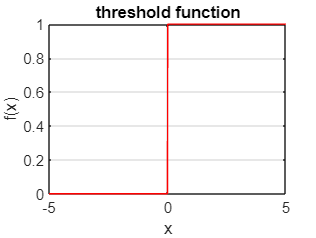

% Threshold function
t = -5:0.01:5;
f = zeros(size(t));

for i = 1:length(t)
    if t(i) > 0
        f(i) = 1;
    end
end

plot(t,f,'r');
xlabel('x');ylabel('f(x)');
title('threshold function');
grid on

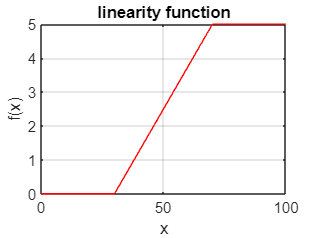


% Linearity function
t = 0:0.05:100;
f = zeros(size(t));
fmin = 0;
fmax = 5.0;
N0 = 30;
N1 = 70;
k = (fmax - fmin)/(N1 - N0);
t0 = k*N1 - 5;

for i = 1:length(t)
    if t(i) > N0 & t(i) < N1
        f(i) = k*t(i) - t0;
    elseif t(i) >= N1
        f(i) = fmax;
    end

end

plot(t,f,'r');
xlabel('x');ylabel('f(x)');
title('linearity function');
grid on

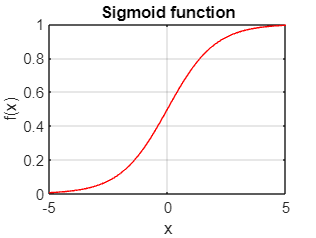


% Sigmoid function
t = -5:0.01:5;
f = zeros(size(t));
T = 1.0;

for i = 1:length(t)
    
    f(i) = 1/(1 + exp(-t(i)/T));

end

plot(t,f,'r');
xlabel('x');ylabel('f(x)');
title('Sigmoid function');
grid on

###  7.2 Backpropagation approximation of Neural Network Design and simulation

% Schema of controlling a plant using Artificial Neural Network

% The plant is y(k) = u(k)^3 + y(k-1)/(1 + y(k-1)^2)
% Input signal is u(k) = 0.5*sin(6pi*t);
% Input vector of neural network x = [u(k) y(k)]
% ANN structure is 2-6-1
% Activation function is sigmoid function
% Initial value of weigths of ANN is random value in [-1;1]
% Learning rate neta = 0.5
% momentum factor alpha = 0.05

clear all; close all;

xite = 0.5; % learning rate
alfa = 0.05; % momentum factor

% Initialisation of inputs and weigths of neural network

wjo = rands(6,1); % weights of output layer
wjo_1 = wjo; wjo_2 = wjo_1;

wij = rands(2,6); % weights of hidden layer
wij_1 = wij; wij_2 = wij;

dwij = 0*wij;

x = [0,0]'; % initial values of u(k) and y(k)

u_1 = 0;
y_1 = 0;

I=[0,0,0,0,0,0]'; % initialization of input of hidden layer
Iout=[0,0,0,0,0,0]'; % initialization of output of hidden layer
FI=[0,0,0,0,0,0]'; % initialization of activation function values

ts = 0.001; % sampling time

for k = 1:1000
    time(k) = k*ts;
    u(k)  = 0.05 * sin(3*pi*time(k)); % control input
    y(k) = u_1^3 + y_1/(1 + y_1^2); % output

    x(1) = u(k);
    x(2) = y(k);

    for j = 1:6
        I(j) = x'*wij(:,j); % input of hidden layer
        Iout(j) = 1 / (1 + exp(-I(j))); % Activation function and Output of hidden layer
    end

    yo(k) = wjo'*Iout; % output of Neural network

    e(k) = y(k) - yo(k); % Error calculation

    wjo = wjo_1 + (xite*e(k))*Iout + alfa*(wjo_1 - wjo_2); % new weights of output layer of ANN

    for j = 1:6
        FI(j) = exp(-I(j))/(1 + exp(-I(j)))^2; % Derivative of activation function xj'
    end

    for i = 1:2
        for j = 1:6
            dwij(i,j) = e(k)*xite*FI(j)*wjo(j)*x(i); % xite * error * dyo/dwij = xite * error * wjo * ( xj' * (1 -xj') * xi )
        end
    end

    wij = wij_1 + dwij + alfa*(wij_1 - wij_2);

    yu = 0;
    for j = 1:6
        yu = yu + wjo(j)*wij(1,j)*FI(j); % Jacobian = dy(k)/du(k)
    end
    dyu(k) = yu;

    % affectation for the after step
    wij_2 = wij_1;wij_1 = wij;
    wjo_2 = wjo_1;wjo_1 = wjo;
    u_1 = u(k);
    y_1 = y(k);
end

clf
figure(1);
plot(time(100:end),y(100:end),'r',time(100:end),yo(100:end),'b');
xlabel('times');ylabel('y and yo');
legend('true output','approximated output');
title('Backpropagation approximation');



clf
figure(2);
plot(time(100:end),y(100:end)-yo(100:end),'r');
xlabel('times');ylabel('error');
title('Backpropagation approximation error');


clf
figure(3);
plot(time(100:end),dyu(100:end));
xlabel('times');ylabel('dyu');
title('Jacobian value identification');

% Plot radial basis function neural network response

close all;

t = out.t;
y = out.y;
% y=y(:,1);
% x=y(:,2);
% h1=y(:,3);
% h2=y(:,4);
% h3=y(:,5);
% h4=y(:,6);
% h5=y(:,7);
figure(1);
plot(t,y(:,1),'k','linewidth',2);
xlabel('time(s)');ylabel('y');
title('Output of Radial Basis Function NN')

figure(2);
plot(y(:,2),y(:,3),'k','linewidth',2);
xlabel('x');ylabel('hj');
hold on;
plot(y(:,2),y(:,4),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,5),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,6),'k','linewidth',2);
hold on;
plot(y(:,2),y(:,7),'k','linewidth',2);
title('Output of hidden RBF NN')